## This is all about plotting in MATLAB

% defining a range in MATLAB
x = 1 : 10

x =      1     2     3     4     5     6     7     8     9    10


% defining a range with a step size
y = 1 : 0.5 : 5

y =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


% calculate the length of these vectors
len = length(y)

len = 9

% negative range
z = -10: -1: -25

z =    -10   -11   -12   -13   -14   -15   -16   -17   -18   -19   -20   -21   -22   -23   -24   -25


t = [1:10]

t =      1     2     3     4     5     6     7     8     9    10


sin(t)

ans =     0.8415    0.9093    0.1411   -0.7568   -0.9589   -0.2794    0.6570    0.9894    0.4121   -0.5440


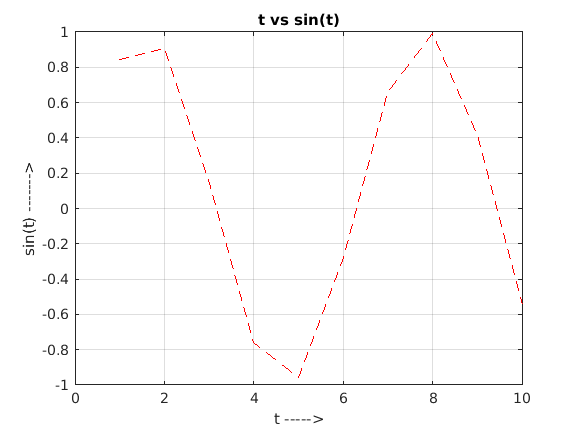

y = sin(t);
plot(t, y, '--r');

grid on
title('t vs sin(t)')
xlabel('t ----->')
ylabel('sin(t) ------->')

% let us define some functions as
t = 0: 0.5: 10

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


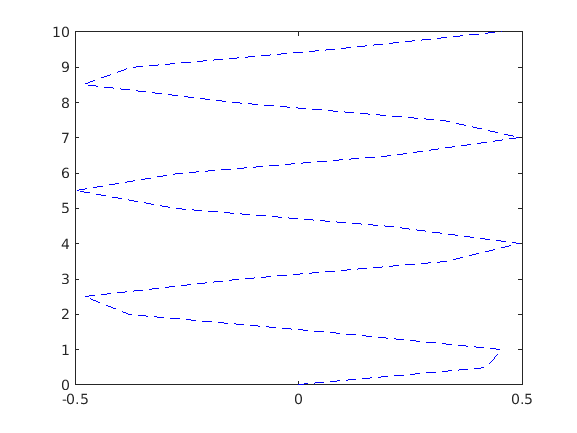

f1 = sin(t);
f2 = cos(t);
f3 = sin(t) .* cos(t);
f4 = exp(t);

plot(f3, t, '--b');

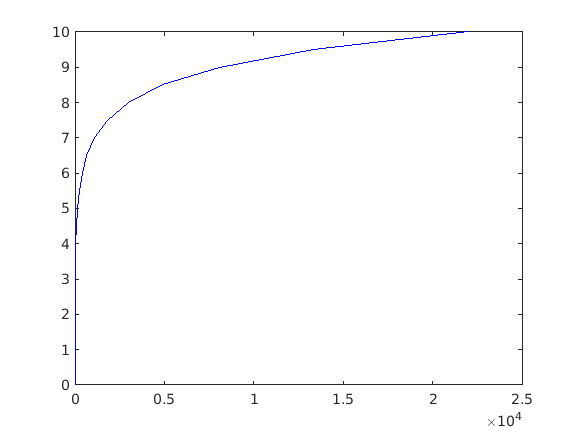


plot(f4, t, '-b');

% linspace => gives n points between x and y
linspace(10, 18, 9)

ans =     10    11    12    13    14    15    16    17    18


x = 0.5;
y = 1.0;
n = 10;
linspace(x, y, n)

ans =     0.5000    0.5556    0.6111    0.6667    0.7222    0.7778    0.8333    0.8889    0.9444    1.0000


%logspace
logspace(1, 8, 8)

ans =           10         100        1000       10000      100000     1000000    10000000   100000000


format long;
logspace(-1, -6, 6)

ans =    0.100000000000000   0.010000000000000   0.001000000000000   0.000100000000000   0.000010000000000   0.000001000000000


% in reverse direction
format short;
linspace(10, 5, 5)

ans =    10.0000    8.7500    7.5000    6.2500    5.0000


whos

  Name      Size              Bytes  Class     Attributes

  ans       1x5                  40  double              
  f1        1x21                168  double              
  f2        1x21                168  double              
  f3        1x21                168  double              
  f4        1x21                168  double              
  len       1x1                   8  double              
  n         1x1                   8  double              
  p         1x1001             8008  double              
  sine      1x629              5032  double              
  t         1x21                168  double              
  x         1x1                   8  double              
  y         1x1                   8  double              
  z         1x16                128  double              



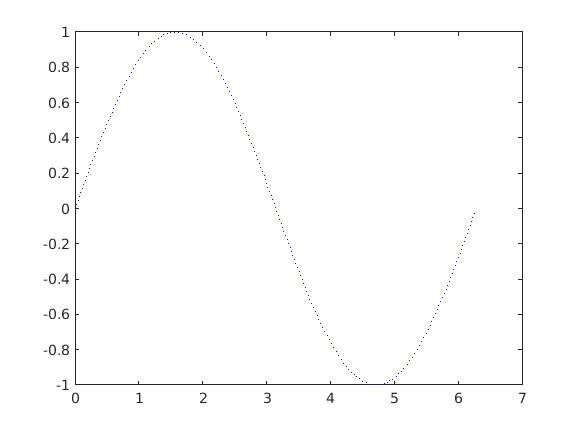

sine = sin([0:0.01:2*pi]);
plot([0:0.01:2*pi], sine, ':b')

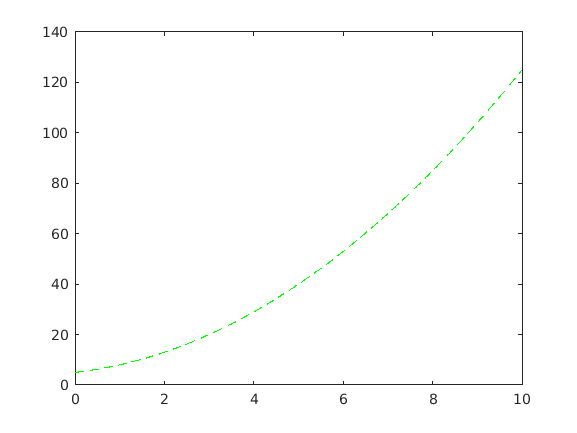

t = [0: 0.01: 10];
p = t .^ 2 + 2 * t + 5;
plot(t, p, '--g')

x = linspace(-1, 1, 100);
y = asin(x)

y =    -1.5708   -1.3694   -1.2856   -1.2209   -1.1660   -1.1175   -1.0733   -1.0325   -0.9943   -0.9582   -0.9239   -0.8911   -0.8596   -0.8292   -0.7997   -0.7712   -0.7434   -0.7163   -0.6898   -0.6639   -0.6385   -0.6135   -0.5890   -0.5649   -0.5412   -0.5178   -0.4947   -0.4719   -0.4493   -0.4270   -0.4049   -0.3830   -0.3613   -0.3398   -0.3185   -0.2973   -0.2762   -0.2553   -0.2345   -0.2137   -0.1931   -0.1726   -0.1521   -0.1317   -0.1113   -0.0910   -0.0708   -0.0505   -0.0303   -0.0101


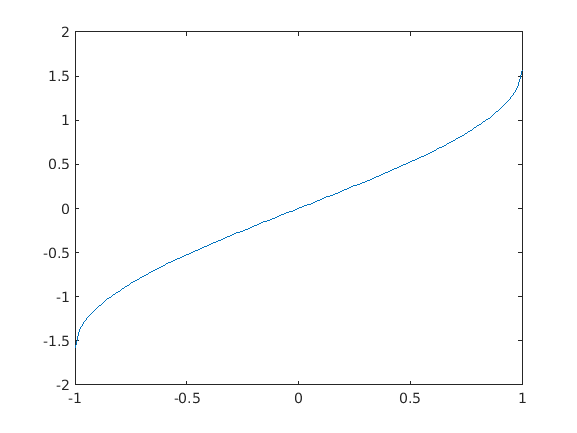

  Name      Size              Bytes  Class     Attributes

  ans       1x5                  40  double              
  f1        1x21                168  double              
  f2        1x21                168  double              
  f3        1x21                168  double              
  f4        1x21                168  double              
  len       1x1                   8  double              
  n         1x1                   8  double              
  p         1x1001             8008  double              
  sine      1x629              5032  double              
  t         1x1001             8008  double              
  x         1x100               800  double              
  y         1x100               800  double              
  z         1x16                128  double              



plot(x, 

y = 5 * y .^ 2 + 5

y = 	1.0e+03 *

    1.5079    1.0385    0.8846    0.7803    0.7010    0.6371    0.5839    0.5386    0.4993    0.4649    0.4345    0.4073    0.3830    0.3610    0.3410    0.3229    0.3063    0.2912    0.2772    0.2645    0.2527    0.2418    0.2318    0.2225    0.2139    0.2060    0.1987    0.1919    0.1856    0.1797    0.1743    0.1694    0.1648    0.1605    0.1566    0.1531    0.1498    0.1468    0.1441    0.1417    0.1395    0.1376    0.1359    0.1344    0.1331    0.1321    0.1313    0.1306    0.1302    0.1300


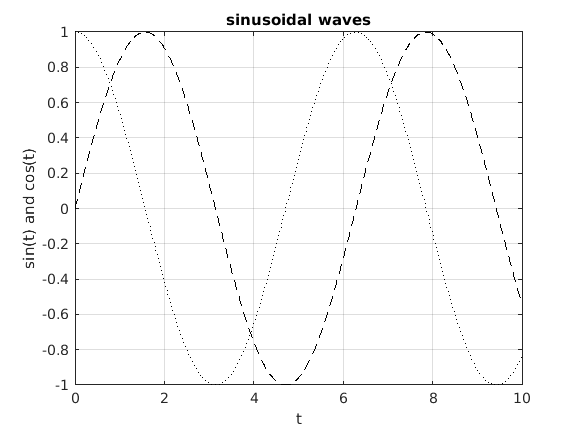






% plotting two at once
x = 0:0.01:10;
y = sin(x);
z = cos(x);
plot(x, y, '--k');
grid on;
hold on;
plot(x, z, ':k');
xlabel("t");
ylabel("sin(t) and cos(t)");
title("sinusoidal waves");
plot(x, y, '--k');
grid on;
hold on;
plot(x, z, ':k');

%% end of notebook